# Eksamensæt

**M3NUM1 Anvendte Numeriske Metoder -- 16-01-2023**

**Mathias Bruun Houmøller -- 202006837 -- Au666097**

## Opgave 1

clear
format short %formater resultater til 4 decimaler

### (1a)

Til opgaven benytter vi functionen eulode.m

%data indsættes
q = 0.5; %kg/s
V = 120; %l
m0 = 30; %kg
rho_V = 1; %kg/l
dYdt = @(t,Y) [-q*Y(1)/ (Y(1) + rho_V * V)]; %funktionen til eulode indsættes som en numersk funktion
%m er omdiffinerede til Y(1) for at indgå i funktionen eulode.

Y0 = [m0]; %Grænseværdi for vores differential ligning.
tidsinterval = [0 720]; %Tidsintervallet vi udregner differential ligningen i.
h = 120; % intervallet hvormed differential ligningen udregnes 0, 120, 240, osv...
[t,Y] = eulode(dYdt,tidsinterval,Y0,h); % kald og input af data i eulode fuktionen (vist ovenfor).
M = Y(:,1); %resultat trækkes ud af funktionen for tydeliggørrelse.
disp(table(t,M,'VariableNames',{'t, sekunder(s)','M, masse(kg)'})) %der laves en tabel med værdierne.

    t, sekunder(s)    M, masse(kg)
    ______________    ____________

           0                 30   
         120                 18   
         240             10.174   
         360             5.4845   
         480             2.8621   
         600             1.4644   
         720            0.74103   



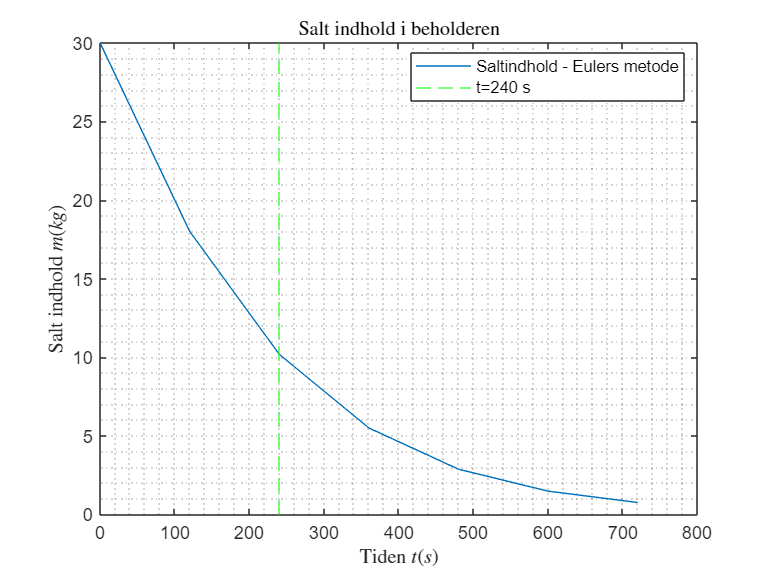

% %der plottes
plot(t,M, 'DisplayName', 'Saltindhold - Eulers metode') %data plottes
hold on
xline(t(3), 'g--', 'DisplayName', 't=240 s'); %markerings linje for bedre overskuelse

% formalier
legend('location', 'best')
title('Salt indhold i beholderen', 'interpreter', 'latex')
xlabel('Tiden $t(s)$', 'interpreter', 'latex')
ylabel('Salt indhold $m(kg)$', 'interpreter', 'latex')
grid('minor')
hold off

**Til tiden 240 s ses det at salt mængden er  10,17 kg,**

### (1b)

h_f = 60; % steps før 
err_f = 0.908; %fejl før

h_e = 180; %steps efter
err_e = 2.886; %fejl efter

Forhorholene er således

h_forhold = h_e/ h_f %forhold

h_forhold = 3

err_forhold = err_e / err_f %forhold

err_forhold = 3.1784

**Vi ser at når skridtene bliver gevet med tre doblet så stiger fejlen med 3 gange. dette stemmer fint overens med det forventede da euler metoden er en lineær fremskrivning (1. orden) og dermed når skridtet halveres halveres fejelen også.**

### (1c)

Den liniær fremskrivning er for grov og overskyder målet. Den evalueres først igen efter at have paseret m=0.

Vi tager det første srkidt hvor vi ser vi rammer de -42

m_720 = 30 + dYdt(0,30) * (720-0)

m_720 = -42

Fordi vi tager en lige linje ned så evalures der først igen efter m=0

dYdt(0,30) % højere m værdi

ans = -0.1000

dYdt(200,10) %mindre m værdi

ans = -0.0385

Det ses også at jo flere skridt der tages jo mere mere falder vores m værdi.

m værdien afgøre hældningen af den lineær kruve så dermed jo flere skridt jo mere afbløedet kurve får vi

Vi plotter for at få et bedre overblik

Y0 = [m0]; 
tidsinterval = [0 2880]; %nu et nyt tids interval
h = 720; %nu et nyt skridt interval
[t,Y] = eulode(dYdt,tidsinterval,Y0,h); 
M = Y(:,1); 

disp(table(t,M,'VariableNames',{'t, sekunder(s)','M, masse(kg)'}))

    t, sekunder(s)    M, masse(kg)
    ______________    ____________

            0                30   
          720               -42   
         1440            151.85   
         2160            -49.24   
         2880            201.28   



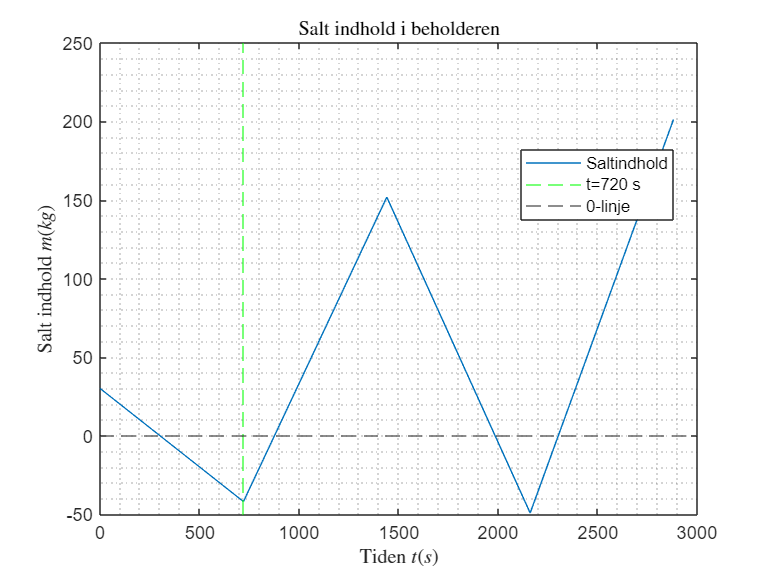


% %der plottes
% set(groot,'defaultLegendInterpreter','latex');
plot(t,M, 'DisplayName', 'Saltindhold') %data plottes
hold on
xline(t(2), 'g--', 'DisplayName', 't=720 s'); 
yline(0, '--', 'DisplayName', '0-linje'); 

% formalier
legend('location', 'best')
title('Salt indhold i beholderen', 'interpreter', 'latex')
xlabel('Tiden $t(s)$', 'interpreter', 'latex')
ylabel('Salt indhold $m(kg)$', 'interpreter', 'latex')
grid('minor')
hold off

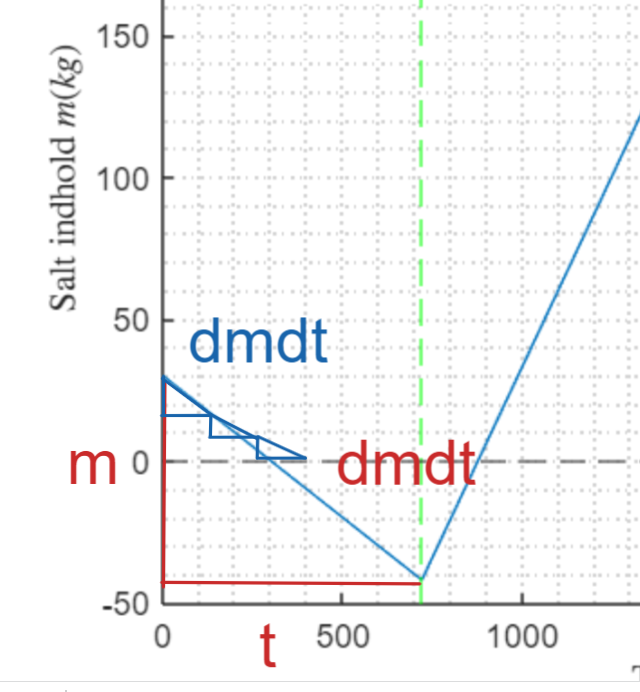

det ses på billedet at flere skridt giver bedre "runding" eller hældning.

### (1d)

Vi benytter funktionen rk4system

clear
q = 0.5; %kg/s
V = 120; %l
m0 = 30; %kg
rho_V = 1; %kg/l
dYdt = @(t,Y) [-q*Y(1)/ (Y(1) + rho_V * V)]; 

% samme inputs som til eulode
Y0 = [m0]; 
tidsinterval = [0 720]; 
h = 120; 
[t,Y] = rk4system(dYdt,tidsinterval,Y0,h);
M = Y(:,1); 

disp(table(t,M,'VariableNames',{'t, sekunder(s)','M, masse(kg)'}))

    t, sekunder(s)    M, masse(kg)
    ______________    ____________

           0                 30   
         120             19.811   
         240             12.747   
         360             8.0425   
         480             5.0046   
         600             3.0854   
         720             1.8908   



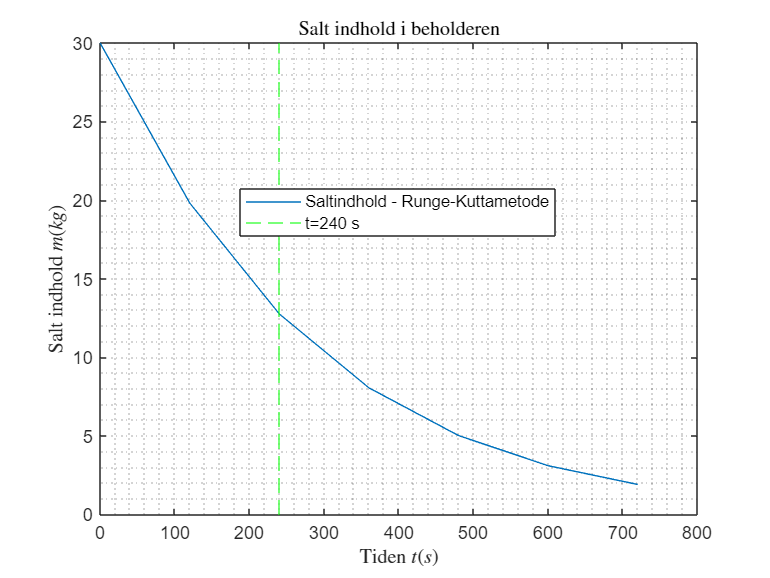



% %der plottes
% set(groot,'defaultLegendInterpreter','latex');
plot(t,M, 'DisplayName', 'Saltindhold - Runge-Kuttametode') %data plottes
hold on
xline(t(3), 'g--', 'DisplayName', 't=240 s'); 

% formalier
legend('location', 'best')
title('Salt indhold i beholderen', 'interpreter', 'latex')
xlabel('Tiden $t(s)$', 'interpreter', 'latex')
ylabel('Salt indhold $m(kg)$', 'interpreter', 'latex')
grid('minor')
hold off

**Til tiden 240 s ses det at salt mængden er  12,75 kg.**

## Opgave 2

clear

### (2a)

% Vi opstiller ligningerne
syms x y z a b c d k

f1 = (a + b *y)^2 - (d - c*x)^2 + k*z + (c * x + b * y) * (c*x-b*y); % = 0
f2 = (b * x^-1 + c) * x + a * z^2 - b*x +d*y - a *(c-z)^2; %=0
f3 = c*z - d*y + k*x - b; %=0
f = [expand(f1); expand(f2); expand(f3)]

$$f = \left(\begin{array}{c} a^{2}+2\,b\,y\,a-d^{2}+2\,c\,x\,d+k\,z\\ b-b\,x+c\,x+d\,y-a\,c^{2}+2\,a\,c\,z\\ c\,z-b-d\,y+k\,x \end{array}\right)$$

For bedre overblik udvide matrixerne hvor det ses at der ikke er nogle variabler i led sammen og igen i højere orden


for i = 1:length(f)
    fprintf(" Ligning %d patielt differentiert for alle varable", i)
    diff(f(i), x)
    diff(f(i), y)
    diff(f(i), z)
end

 Ligning 1 patielt differentiert for alle varable

$$ans = 2\,c\,d$$

$$ans = 2\,a\,b$$

$$ans = k$$

 Ligning 2 patielt differentiert for alle varable

$$ans = c-b$$

$$ans = d$$

$$ans = 2\,a\,c$$

 Ligning 3 patielt differentiert for alle varable

$$ans = k$$

$$ans = -d$$

$$ans = c$$

Der laves partiel differentiering og det ses kun konstanter kommer ud.

Dette kan også gøres med den indbyggede function jacobian.

jacobian(f, [x, y, z])

$$ans = \left(\begin{array}{ccc} 2\,c\,d & 2\,a\,b & k\\ c-b & d & 2\,a\,c\\ k & -d & c \end{array}\right)$$

**Det ses således at ligningssystemet er lineært.**

### (2b)

Vi benytter den indbyggede function til at omskrive til Coeficent matrixen A og løsnings vektoren B

[A, B] = equationsToMatrix(f, [x, y, z])

$$A = \left(\begin{array}{ccc} 2\,c\,d & 2\,a\,b & k\\ c-b & d & 2\,a\,c\\ k & -d & c \end{array}\right)$$

$$B = \left(\begin{array}{c} d^{2}-a^{2}\\ a\,c^{2}-b\\ b \end{array}\right)$$

Her til kan variablerne i X vektoren løses.

X = [x; y; z]

$$X = \left(\begin{array}{c} x\\ y\\ z \end{array}\right)$$

### (2c)

clear
syms x y z
a = -1;
b = 4;
c = 2;
d = -3;
k = 3;


A = [2*c*d, 2*a*b, k
    c - b, d, 2*a*c
    k, -d, c]

A =    -12    -8     3
    -2    -3    -4
     3     3     2


B = [d^2 - a^2; a*c^2 - b; b]

B =      8
    -8
     4


X_sol = linsolve(A,B) % der benyttes den indbyggede solver. der kunne også benyttes X_sol=A\B til at løslingningssytemet

X_sol =    12.0000
  -16.0000
    8.0000


Vi får således resultaterne $x = 12,\ y = -16,\ z=8$.

## Opgave 3

clear

### (3a)

Vi laver funktionen (findes også i bunden af dokumentet)

Rejsetider;
pktfolge = [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 1];
trt = totalrejsetid_min(rejsetider,pktfolge)

trt = 28.8000

### (3b)

Vi retter funktionen

pktfolge0 = [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 1];
[suboptpktfolge,subopttid] = subopttotalrejsetid(rejsetider,pktfolge0)

suboptpktfolge =      1    12    20    17     4     9     5     8    15     6    18    11    13     2    14    16     7    10     3    19     1


subopttid = 11.7000

## Opgave 4

clear

### (4a)

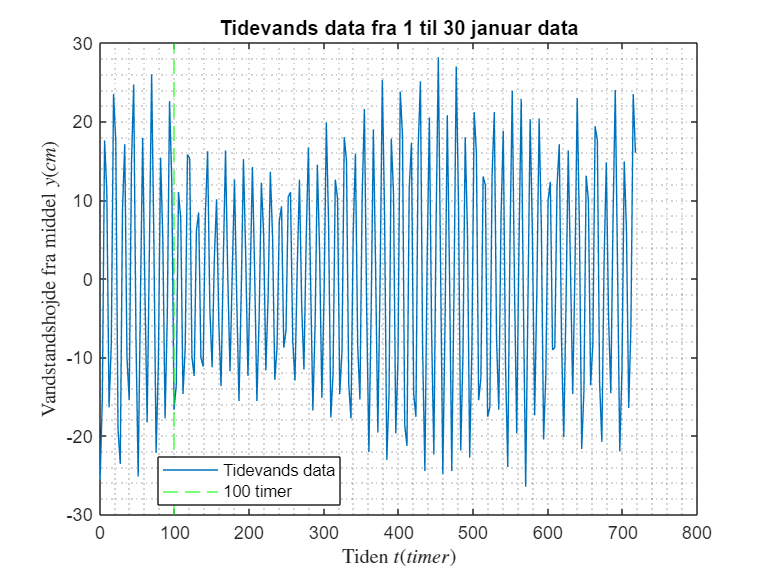

TidevandAarhusJanuar2023; %henter data
dt = 3;                   % Samplingsinterval (s)
t = 0:dt:24*30 - 3; % 30 dag med 24 timer - 3 timer på sidste dag
plot(t,y, 'DisplayName', 'Tidevands data') %data plottes
hold on
xline(100, 'g--', 'DisplayName', '100 timer'); 
% formalier
legend('location', 'best')
title('Tidevands data fra 1 til 30 januar data')
xlabel('Tiden $t(timer)$', 'interpreter', 'latex')
ylabel('Vandstandshojde fra middel $y(cm)$', 'interpreter', 'latex')
grid('minor')
hold off

Der måles 8 toppe på 100 timer

format longg
f = 8/(100 * 60 * 60) %omskrives til sekunder 

f =       2.22222222222222e-05


**således fås frekvensen 0,00002 Hz.**

eller

f = 8/(100) 

f =                       0.08



$$f = 0,08 \ Hr^{-1}$$


### (4b)

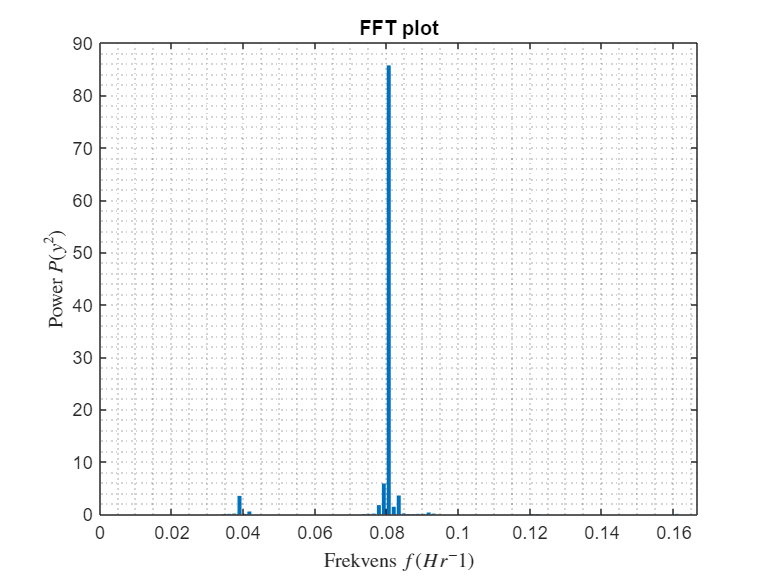

n = length(y);              % Antal samplinger % her vælges alt data som sample
T = n*dt;                   % Signallængde (s) % Tiden det tager at køre smplet igennem
Y = fft(y)/n;               % FFT af a (mm)
fs = 1/dt;                  % Samplingsfrekvens (Hz) %Frekvensen hvormed der tages sampels
fmax = fs/2;                % Maks frekvens (Hz)
df = 1/T;                   % Frekvensstep (Hz)
f = (0:n-1)*df;             % Frekvensvektor (Hz) % alle frekvensskridt der gennemgåes
P = real(Y).^2 + imag(Y).^2;% Powervektor (mm^2) % Her lægges real delen og imaginær delens sammen og forstærkes så de kun er positive
bar(f,P);                   % Plot af powerspektrum %plottes som barplot for bedre overskuelighed
xlim([0 fmax]);             % Afgræns frekvensakse % så der kun ses på et område der ikke gentager en frekvens

% Formalier
title('FFT plot')
xlabel('Frekvens $f(Hr^-1)$', 'interpreter', 'latex')
ylabel('Power $P(y^2)$', 'interpreter', 'latex')
grid('minor')

### (4c)

result = find(P==max(P)) % vi finder postionen i power vektoren hvor den største frekvens viser sig

result =     59   183


% Her vælges første tal da andet tal blot af en gentagelse af frekvensen
% Vi kan nu finde frekvensen for det stærkeste signal
f_strong = f(result(1))

f_strong =         0.0805555555555556


T = 1/ f_strong % perioden findes

T =           12.4137931034483


### Frekvensen er således fundet til $f=0,0806\ Hr^{-1}$

og perioden er **T = 12,4 timer**

## Opgave 5

clear

### (5a)

I opgaven benyttes funktionen bisect

Vi opstiller funktion og data

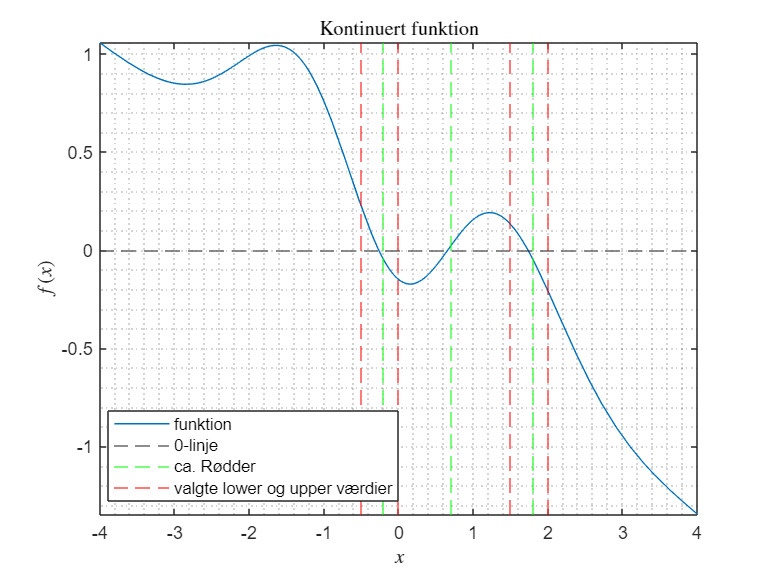

f = @(x) x.^2 .* exp(-0.5*x.^2) - 0.3*x - 0.15;
es = 0.1; % %
xl = -4;
xu = 4;

% %der plottes
fplot(f,[xl, xu], 'DisplayName', 'funktion') %data plottes
hold on
yline(0, '--', 'DisplayName', '0-linje')
xline([-0.2], 'g--', 'DisplayName', 'ca. Rødder'); 
xline([0.7 1.8], 'g--','HandleVisibility','off');

xline([-0.5], 'r--', 'DisplayName', 'valgte lower og upper værdier'); 
xline([0, 1.5, 2], 'r--','HandleVisibility','off');

% formalier
legend('location', 'best')
title('Kontinuert funktion', 'interpreter', 'latex')
xlabel('$x$', 'interpreter', 'latex')
ylabel('$f(x)$', 'interpreter', 'latex')
grid('minor')
hold off

omr = [-0.5, 0, 1.5, 2]; %området vi vil lede efter løsninger i
for i = 1:length(omr)
    if i == length(omr)
        break
    end
    
    xl = omr(i);
    xu = omr(i+1);
    fprintf('rod imellem %f og %f er:', xl, xu )
    [root,fx,ea,iter]=bisect(f,xl,xu,es)
    disp(' ---------------------------------   ')
    roots(i) = root;
    eas(i) = ea;
end

rod imellem -0.500000 og 0.000000 er:

root =            -0.268310546875


fx =       -6.1522934267727e-05


ea =         0.0909918107370337


iter =     11


 ---------------------------------   


rod imellem 0.000000 og 1.500000 er:

root =            0.6558837890625


fx =       0.000163879046931215


ea =         0.0558347292015634


iter =     12


 ---------------------------------   


rod imellem 1.500000 og 2.000000 er:

root =               1.7314453125


fx =       0.000190730358595875


ea =         0.0564015792442188


iter =      9


 ---------------------------------   


Upper og lower limit værdier vælges da de er nemme og hurtige at aflæse og kun har en rod imellem hver. Således kan vi benytte dem i et forloop med bisect for at få alle rødder ud.

Vi får således:

roots

roots =            -0.268310546875           0.6558837890625              1.7314453125


eas

eas =         0.0909918107370337        0.0558347292015634        0.0564015792442188


Vi finder rødderne med fejl

for i = 1:length(roots)
    y_err = abs(eas(i) * roots(i) /100)
    y_with_err = [roots(i) - y_err, roots(i) + y_err]
end

y_err =             0.000244140625


y_with_err =              -0.2685546875            -0.26806640625


y_err =            0.0003662109375


y_with_err =             0.655517578125                   0.65625


y_err =               0.0009765625


y_with_err =                 1.73046875               1.732421875


Det ses at alle rødder er præcise ved afrunding til 2 decimaler.

Vi får således røderne:

 
$$r_1 = -0,27 \\ r_2 =  0,66 \\ r_3 =  1,73$$


efter afrundede usikkerheder.